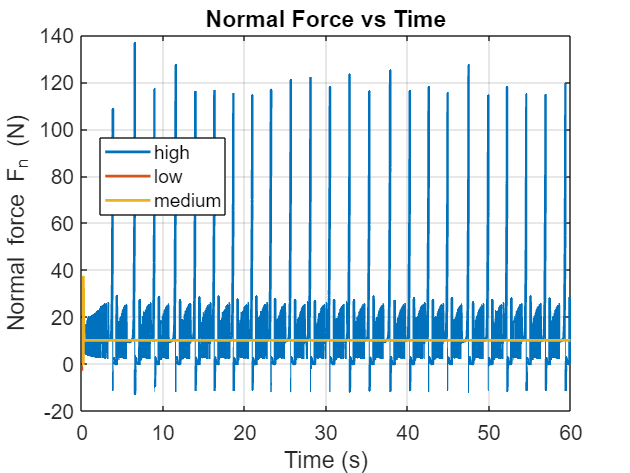

Saved: C:\Users\allen\OneDrive\GC-College\2151final\graphs\undisfor10_F_n.png


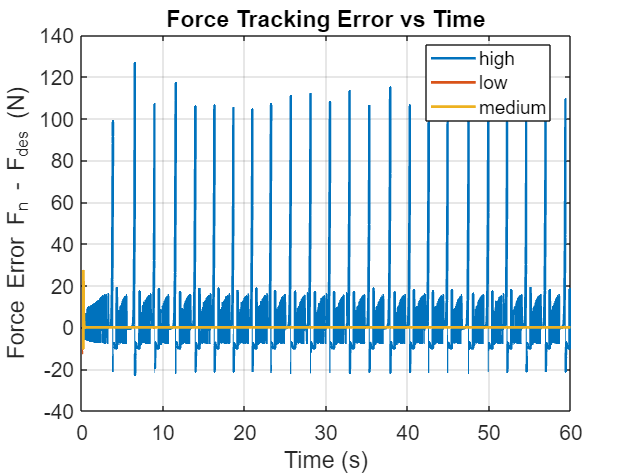

Saved: C:\Users\allen\OneDrive\GC-College\2151final\graphs\undisfor10_F_err.png


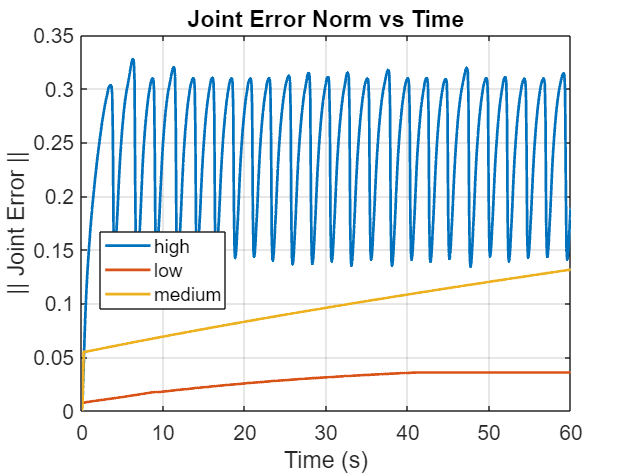

Saved: C:\Users\allen\OneDrive\GC-College\2151final\graphs\undisfor10_joint_err_norm.png


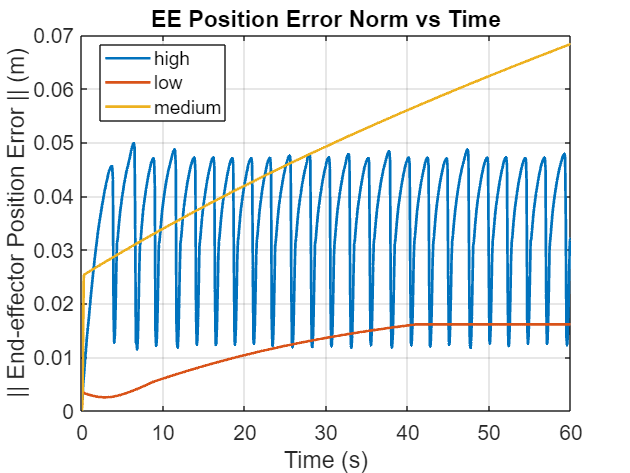

Saved: C:\Users\allen\OneDrive\GC-College\2151final\graphs\undisfor10_ee_err_norm.png


%% ============================================================
%  Script: plot_force_metrics.m
%  Purpose:
%    - Load a CSV of LQI force-control results
%    - Plot:
%         1) F_n vs time
%         2) F_err vs time
%         3) joint_err_norm vs time
%         4) ee_err_norm vs time
%    - Save each plot automatically as a PNG whose filename
%      includes the CSV base name and metric name.
% ============================================================

clear; clc; close all;

%% ------------------- CONFIG -------------------------
% CSV file to load
csvfile = 'undisfor10.csv';   % <-- change this if needed

% Optional: folder to save PNGs in
outDir = 'C:\Users\allen\OneDrive\GC-College\2151final\graphs';
if ~exist(outDir, 'dir')
    mkdir(outDir);
end

% Get base name of CSV (e.g., 'undisfor' from 'undisfor.csv')
[~, csvname, ~] = fileparts(csvfile);

%% ------------------- Load CSV -------------------------
T = readtable(csvfile);

% Ensure 'height' is categorical
if ~iscategorical(T.height)
    T.height = categorical(T.height);
end

heights = categories(T.height);  % e.g. {'low','medium','high'}

%% ----------- Metric definitions to plot --------------
% Each row: {metric_name, y_label, title_str}
metrics = {
    "F_n",            "Normal force F_n (N)",                        "Normal Force vs Time";
    "F_err",          "Force Error F_n - F_{des} (N)",               "Force Tracking Error vs Time";
    "joint_err_norm", "|| Joint Error ||",                           "Joint Error Norm vs Time";
    "ee_err_norm",    "|| End-effector Position Error || (m)",       "EE Position Error Norm vs Time"
};

%% --------------- Generate & Save All Plots ------------
for i = 1:size(metrics, 1)
    metric_name = metrics{i, 1};
    y_label     = metrics{i, 2};
    title_str   = metrics{i, 3};

    plot_metric(T, heights, metric_name, y_label, title_str, csvname, outDir);
end


disp('All plots generated and saved as PNGs.');

All plots generated and saved as PNGs.



%% ============================================================
% Helper function: plot one metric vs time for all heights
% ============================================================

function plot_metric(T, heights, metric_name, y_label, title_str, csvname, outDir)

    fig = figure('Color','w'); hold on; box on;

    % Distinct colors for each height
    colors = lines(numel(heights));

    for i = 1:numel(heights)
        h = heights{i};
        idx = T.height == h;

        t = T.time(idx);
        y = T.(metric_name)(idx);

        plot(t, y, 'LineWidth', 1.8, 'Color', colors(i,:));
    end

    xlabel('Time (s)');
    ylabel(y_label);
    title(title_str, 'Interpreter', 'none');
    legend(heights, 'Location', 'best');
    grid on;

    set(gca, 'FontSize', 14);

    % Build filename: <outDir>/<csvname>_<metric_name>.png
    filename = fullfile(outDir, sprintf('%s_%s.png', csvname, metric_name));

    % Save figure as PNG (high resolution)
    exportgraphics(fig, filename, 'Resolution', 300);

    fprintf('Saved: %s\n', filename);
end
